clear variables;
close all;
hold on;
figure(1);
a=2;b=-5;c=1;
x2=-3:0.1:3;
y2=-2.5:0.1:4;
z2=-8:1:8;
[X2,Y2]=meshgrid(x2,y2);
Z2=-(a*X2+b*Y2)/c;
C(:,:,1)=zeros(size(Z2)); % red
C(:,:,2)=0.8*ones(size(Z2)); % green
C(:,:,3)=0.8*ones(size(Z2)); % blue
mesh(X2,Y2,Z2,C);

Xi = -2+(2- -2)*rand(1,10);
Yi = -2+(2- -2)*rand(1,10);
Zi = -2+(2- -2)*rand(1,10);
plot3(Xi,Yi,Zi,'.b');

n=[a; b; c];
n=n/norm(n);

P = eye(3) - n*n';

U = [Xi;Yi;Zi];
K=10;
V = zeros(3,K);
for k=1:K
    V(:,k)=P*U(:,k);
end
plot3(V(1,:),V(2,:),V(3,:),'*k');

for k=1:K
    plot3([V(1,k),U(1,k)],[V(2,k),U(2,k)],[V(3,k),U(3,k)],'k');
end
axis equal;
axis ([-4,4,-4,4,-8,8])

on perturbe les coordonnées des points projetés

delta=0.5;
dV=-delta/2+delta*rand(3,K);
W=V+dV;

affichage des points perturbés (triangles)

plot3(W(1,:),W(2,:),W(3,:),'vk');

calcul du plan passant au plus près des points perturbés (résolution

au sens des moindre carrés d’un système Au=v, avec A et v à définir)

A=[W(1,:)',W(2,:)'];
b= W(3,:)';
x=(A'*A)\A'*b;

affichage du plan (en pointillés)

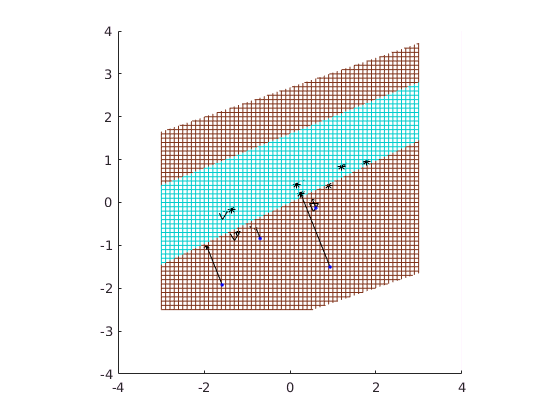

a=-x(1,1);b=-x(2,1);c=1;
x2=-3:0.1:3;
y2=-2.5:0.1:4;
z2=-8:1:8;
[X2,Y2]=meshgrid(x2,y2);
Z2=-(a*X2+b*Y2)/c;
C(:,:,1)=0.5*ones(size(Z2)); % red
C(:,:,2)=0.2*ones(size(Z2)); % green
C(:,:,3)=0.1*ones(size(Z2)); % blue
mesh(X2,Y2,Z2,C);

Calculer l’angle 𝛼 que fait ce nouveau plan avec le 1er plan de projection

n2 = [a; b; c];
n2=n2/norm(n2);
alpha = acos(dot(n,n2))

alpha = 0.1326